clear; close all; clc;

%% 1. CONFIGURATION & PARAMÈTRES (Modèle F1 Dynamique)
% ---------------------------------------------------------
filename = fullfile(pwd, 'Circuits_Data', 'de-1927.geojson'); % Ton fichier
ds = 2.0; 

% Véhicule
m = 750;           % Masse (kg)
L = 3.4;           % Empattement (Wheelbase)
lf = 1.8;          % Distance CG -> Avant
lr = L - lf;       % Distance CG -> Arrière
h_cg = 0.3;        % Hauteur du Centre de Gravité (Crucial pour transfert de charge)
F_max = 16000;     % Force de traction max (N)

% Moteur / Freins
P_max = 750000;    
F_brake_max = 30000;

% Aérodynamisme (Répartition Avant/Arrière importante !)
rho = 1.225; Area = 1.5;
Cl = 3.5;          % Downforce total
Cd = 0.9;
Aero_bal = 0.45;   % 45% de l'aéro sur l'avant (Balance)

% Pneus (Modèle Linéaire saturé)
mu_x = 1.7;        % Grip Longitudinal
mu_y = 1.6;        % Grip Latéral
C_alpha_f = 120000; % Rigidité Pneu Avant (N/rad)
C_alpha_r = 180000; % Rigidité Pneu Arrière (N/rad)

g = 9.81;

%% 2. GÉNÉRATION PISTE (Idem version précédente)
% ---------------------------------------------------------
% (Chargement simplifié pour ne pas surcharger le code)
try
    jsonText = fileread(filename); data = jsondecode(jsonText);
    if isfield(data,'features'), raw=data.features(1).geometry.coordinates; else, raw=data.geometry.coordinates; end
    lon=raw(:,1); lat=raw(:,2);
catch, error('Fichier introuvable'); end

lat0=lat(1); lon0=lon(1); R_earth=6371000;
x_raw=R_earth*deg2rad(lon-lon0)*cos(deg2rad(lat0)); y_raw=R_earth*deg2rad(lat-lat0);
if norm([x_raw(1)-x_raw(end), y_raw(1)-y_raw(end)])>5, x_raw(end+1)=x_raw(1); y_raw(end+1)=y_raw(1); end

d2=diff(x_raw).^2+diff(y_raw).^2; is_mov=[true; d2>1e-5];
x_c=x_raw(is_mov); y_c=y_raw(is_mov);
dist_s=sqrt(diff(x_c).^2+diff(y_c).^2); t_raw=[0; cumsum(dist_s)];
pp_x=spline(t_raw,x_c); pp_y=spline(t_raw,y_c);
S=0:ds:t_raw(end); x_track=ppval(pp_x,S); y_track=ppval(pp_y,S);

dx=Gradient(x_track,ds); dy=Gradient(y_track,ds);
ddx=Gradient(dx,ds); ddy=Gradient(dy,ds);
curvature=(dx.*ddy-dy.*ddx)./(dx.^2+dy.^2).^(1.5);
curvature(abs(curvature)>0.2)=0.2*sign(curvature(abs(curvature)>0.2));
%% 3. CALCUL DES LIMITES DYNAMIQUES (Le Coeur du Sujet)
% ---------------------------------------------------------
fprintf('Calcul des limites dynamiques (Équilibre des Essieux)...\n');

Calcul des limites dynamiques (Équilibre des Essieux)...


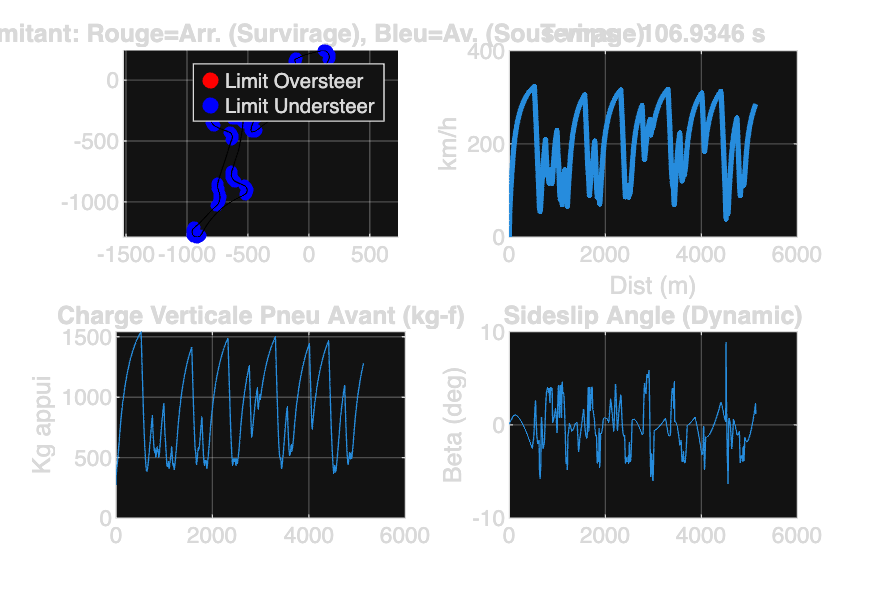

N = length(S);
v_limit = zeros(1, N);
limiter_type = zeros(1, N); % 1=Rear (Oversteer), 2=Front (Understeer)

for i = 1:N
    k = abs(curvature(i));
    
    if k < 1e-5
        v_limit(i) = 360/3.6; % Ligne droite
        continue;
    end
    
    % On cherche la vitesse V max qui respecte l'équilibre des moments
    % Équation : F_lat_front * lf = F_lat_rear * lr  (Pour ne pas tourner sur soi-même)
    % Et : F_lat <= mu_y * Force_Verticale
    
    % Résolution numérique iterative (Bisection) rapide
    v_low = 0; v_high = 150; % m/s
    for iter = 1:10
        v_test = (v_low + v_high)/2;
        
        % 1. Forces Aero
        Fz_aero = 0.5 * rho * Area * Cl * v_test^2;
        Fz_f_aero = Fz_aero * Aero_bal;
        Fz_r_aero = Fz_aero * (1 - Aero_bal);
        
        % 2. Forces Verticales Totales (Statique + Aero)
        % (On néglige le transfert latéral ici pour simplifier)
        Fz_f = (m * g * lr / L) + Fz_f_aero;
        Fz_r = (m * g * lf / L) + Fz_r_aero;
        
        % 3. Grip Latéral Max Disponible par essieu
        Fy_f_max = mu_y * Fz_f;
        Fy_r_max = mu_y * Fz_r;
        
        % 4. Force Latérale Requise (Force Centrifuge)
        F_centri = m * v_test^2 * k;
        
        % 5. Répartition requise pour l'équilibre (Moment Balance)
        % Fy_f * lf = Fy_r * lr   ET   Fy_f + Fy_r = F_centri
        Fy_f_req = F_centri * lr / L;
        Fy_r_req = F_centri * lf / L;
        
        % 6. Vérification
        if (Fy_f_req <= Fy_f_max) && (Fy_r_req <= Fy_r_max)
            v_low = v_test; % Ça passe, on essaie plus vite
        else
            v_high = v_test; % Ça glisse, on ralentit
            
            % Qui a lâché en premier ?
            if Fy_r_req > Fy_r_max
                limiter_type(i) = 1; % Arrière (Survirage dangereux)
            else
                limiter_type(i) = 2; % Avant (Sous-virage)
            end
        end
    end
    v_limit(i) = v_low;
end

%% 4. OPTIMISATION AVEC TRANSFERT DE CHARGE (Longitudinal)
% ---------------------------------------------------------
v_fwd = zeros(1, N); 
v_bwd = zeros(1, N); v_bwd(end) = v_limit(end);

% --- Forward Pass ---
for i = 1:N-1
    v = max(v_fwd(i), 5);
    k = abs(curvature(i));
    
    % A. Calcul Aero
    F_drag = 0.5*rho*Area*Cd*v^2;
    F_down = 0.5*rho*Area*Cl*v^2;
    
    % B. Transfert de Charge (Estimation simplifiée avec accélération précédente)
    % On suppose une accélération max possible de ~1g pour estimer le transfert
    acc_est = F_max/m; 
    load_transfer = (m * acc_est * h_cg) / L; 
    
    % C. Grip Arrière (Propulsion)
    % En accélération, le poids va vers l'arrière (+ load_transfer)
    Fz_r = (m*g*lf/L) + (F_down*(1-Aero_bal)) + load_transfer;
    
    % D. Cercle de Friction sur les roues ARRIÈRE (Limitant pour propulsion)
    F_lat_r_req = (m * v^2 * k) * (lf/L); % Part de la centrifuge sur l'arrière
    F_max_r = mu_x * Fz_r; % Grip dispo
    
    if F_lat_r_req >= F_max_r
        F_tract_max = 0;
    else
        F_tract_max = sqrt(F_max_r^2 - F_lat_r_req^2);
    end
    
    % E. Moteur vs Grip
    F_eng = min(F_max, P_max/v);
    F_net = min(F_eng, F_tract_max) - F_drag;
    
    a = F_net/m;
    v_next = sqrt(v_fwd(i)^2 + 2*a*ds);
    v_fwd(i+1) = min(v_next, v_limit(i+1));
end

% --- Backward Pass ---
for i = N:-1:2
    v = max(v_bwd(i), 5);
    k = abs(curvature(i));
    
    F_drag = 0.5*rho*Area*Cd*v^2;
    F_down = 0.5*rho*Area*Cl*v^2;
    
    % Freinage : Poids vers l'avant -> Arrière délesté !
    % C'est souvent l'arrière qui bloque en premier au freinage
    % On approxime freinage max ~ 4g (F1)
    acc_est = 4*g; 
    load_transfer = (m * acc_est * h_cg) / L;
    
    % On vérifie le grip global (simplification : freinage sur 4 roues)
    Fz_tot = m*g + F_down;
    
    % Cercle friction global
    F_lat_tot = m * v^2 * k;
    F_grip_tot = mu_x * Fz_tot;
    
    if F_lat_tot >= F_grip_tot
        F_brake_avail = 0;
    else
        F_brake_avail = sqrt(F_grip_tot^2 - F_lat_tot^2);
    end
    
    F_net_brake = min(F_brake_max, F_brake_avail) + F_drag;
    
    a = F_net_brake/m;
    v_prev = sqrt(v_bwd(i)^2 + 2*a*ds);
    v_bwd(i-1) = min(v_prev, v_limit(i-1));
end

v_final = min(v_fwd, v_bwd);
T_total = sum(ds./max(v_final,1));

%% 5. VISUALISATION DYNAMIQUE
% ---------------------------------------------------------
figure('Name','Dynamic Model Analysis','Color','w','Position',[50 50 1200 800]);

% Trajectoire colorée par le facteur limitant
subplot(2,2,1);
hold on;
% Tracer les zones limitées par l'arrière (Survirage) en Rouge
idx_over = (limiter_type == 1);
scatter(x_track(idx_over), y_track(idx_over), 20, 'r', 'filled');
% Tracer les zones limitées par l'avant (Sous-virage) en Bleu
idx_under = (limiter_type == 2);
scatter(x_track(idx_under), y_track(idx_under), 20, 'b', 'filled');
plot(x_track, y_track, 'k-', 'LineWidth', 0.5);
axis equal; grid on;
title('Facteur Limitant: Rouge=Arr. (Survirage), Bleu=Av. (Sous-virage)');
legend('Limit Oversteer', 'Limit Understeer');

% Profil Vitesse
subplot(2,2,2);
plot(S, v_final*3.6, 'LineWidth', 2);
ylabel('km/h'); xlabel('Dist (m)'); title(['Temps : ' num2str(T_total) ' s']);
grid on;

% Load Transfert Estimation
subplot(2,2,3);
acc_long = diff([0 v_final]).^2/(2*ds); 
acc_long(diff([0 v_final])<0) = -acc_long(diff([0 v_final])<0);
Fz_front_dyn = (m*g*lr/L) - (m*acc_long*h_cg/L) + (0.5*rho*Area*Cl*v_final.^2 * Aero_bal);
plot(S, Fz_front_dyn/9.81);
title('Charge Verticale Pneu Avant (kg-f)'); ylabel('Kg appui');
grid on;

% Sideslip Estimation (Avec rigidité dynamique)
subplot(2,2,4);
yaw_rate = v_final .* curvature;
% Beta dynamique approx (Eq 15 Tang améliorée avec loads)
% On pondère par la charge verticale réelle
Cr_dyn = C_alpha_r .* (Fz_front_dyn ./ (m*g)); % Approximation variation rigidité
beta = ((m*lf)./(L*C_alpha_r)) .* v_final .* yaw_rate + (lr/L).*curvature*lf;
plot(S, beta*(180/pi));
ylabel('Beta (deg)'); title('Sideslip Angle (Dynamic)');
grid on;


function d=Gradient(f,ds), n=length(f); d=zeros(size(f)); d(1)=(f(2)-f(1))/ds; d(n)=(f(n)-f(n-1))/ds; d(2:n-1)=(f(3:n)-f(1:n-2))/(2*ds); end